# Rozwiązywanie równań różniczkowych

Równania różniczkowe to równania przedstawiające zależność między funkcją a pochodnymi tej funkcji. 

Przykład: Należy znaleźć rozwiązanie równania:


$$\frac{d^2x(t)}{dt^2} + 3 \frac{dx(t)}{dt} + 2x = 0$$


z warunkami początkowymi:


$$x(0)=0 $$
 

$\frac{dx}{dt}(0) = 2$.

Równanie jest liniowe, jednorodne i o stałych współczynnikach, więc można rozwiązać, stosując równanie charakterystyczne. 

Przyjmujemy, że rozwiązanie ma postać:

$x(t) = e^{\lambda t}
$,

gdzie $\lambda$ jest wartością, którą należy znaleźć. 

Podstawiając tę postać do równania różniczkowego, otrzymujemy równanie charakterystyczne:


$$\lambda^2 + 3\lambda + 2 = 0$$


Równanie charakterystyczne jest kwadratowe, więc rozwiązujemy je za pomocą wzoru na pierwiastki równania kwadratowego:

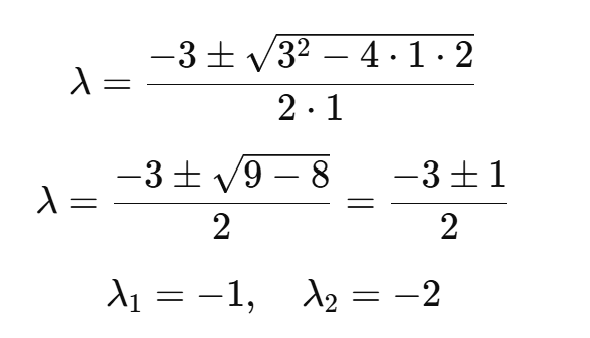

**Ogólne rozwiązanie równania różniczkowego**

Ponieważ pierwiastki są rzeczywiste i różne, ogólne rozwiązanie równania to:


$$x(t) = C_1 e^{\lambda_1 t} + C_2 e^{\lambda_2 t}$$


Podstawiając wartości:

$\lambda_1 = -1;  \lambda_2 = -2$:


$$x(t) = C_1 e^{-t} + C_2 e^{-2t}$$


Stosujemy warunki początkowe, aby wyznaczyć wartości $C_1$ i $C_2$:

Pierwszy warunek początkowy:


$$x(0)=0:$$



$$x(0) = C_1 e^0 + C_2 e^0 = C_1 + C_2 = 0$$


Zatem:

$C_1 = -C_2$.

Drugi warunek początkowy:

$\frac{dx}{dt}(0) = 2$:

Najpierw obliczamy pochodną $x(t)$:


$$\frac{dx}{dt}=-C_{1}e^{-t}-2C_{2}e^{-2t}$$


Podstawiamy $t=0$:


$$\frac{dx}{dt}(0) = -C_1 - 2 C_2 = 2$$


Wstawiając


$$C_1 = -C_2$$



$$ -(-C_2) - 2 C_2 = 2 
$$



$$C_2 - 2 C_2 = 2
$$



$$-C_2 = 2 \Rightarrow C_2 = -2$$


Zatem $C_1 = 2$.

**Rozwiązanie końcowe**

Podstawiając wartości:


$$ C_1 = 2; C_2 = -2,$$


otrzymujemy rozwiązanie analityczne:


$$x(t) = 2 e^{-t} - 2 e^{-2t}$$


To samo równanie zostanie obliczone za pomocą Symbolic Math Toolbox w Matlab.

## Symbolic Math Toolbox

Wykorzystująć Symbolic Math Toolbox należy zadklarować zmienne.

syms x y(t);

Używamy funkcji *dsolve* do rozwiązania równania:

$
\frac{d^2x}{dt^2} + 3\frac{dx}{dt}+2x=0$,

 przy warunkach początkowych:

 *x(0) = 0,*

 
$$\frac{dx}{dt}(0) = 2 $$


y1 = dsolve('D2x + 3*Dx + 2*x = 0', 'x(0) = 0', 'Dx(0) = 2')

$$y1 = 2\,{\mathrm{e}}^{-2\,t}\,\left({\mathrm{e}}^{t}-1\right)$$

lub inny zapis tej samej zależności:


$$y1=2e ^{-t} -2e^{-2t}$$


To rozwiązanie jest sumą dwóch wykładniczych funkcji malejących, co jest zgodne z charakterystycznym rozwiązaniem równań różniczkowych liniowych o stałych współczynnikach, gdzie charakterystyki równania mają rzeczywiste, ujemne pierwiastki.

Rozwiązanie pokazuje, że y maleje do zera, gdy:

$t \to \infty$,

co jest zgodne z układem tłumionym, gdzie wartości początkowe zanikają w miarę upływu czasu.

W przyszłych wersjach MATLAB-a zostanie usunięte wsparcie dla przekazywania równań różniczkowych jako tekstu (ciągów znaków lub wektorów znakowych) do funkcji takich jak `dsolve`. Obecnie można jeszcze używać równań w formacie tekstowym, np. `dsolve('Dy = -3*y')`, ale ten sposób będzie przestarzały i przestanie działać w przyszłych wersjach.

Zamiast przekazywać równania różniczkowe jako tekst, MATLAB zaleca korzystanie z podejścia symbolicznego przy użyciu funkcji `syms`.

Oto kroki:

Użyj `syms` do zadeklarowania zmiennej funkcji zależnej od czasu. 

Na przykład:

syms y(t)

Tutaj `y(t)` definiuje `y` jako funkcję zależną od `t`, co pozwala na bardziej precyzyjne manipulacje matematyczne.

**Definiowanie równania różniczkowego**:

Zamiast `Dy` (pierwszej pochodnej) jako tekstu, należy użyć `diff(y, t)` do wyrażenia pochodnej w stosunku do `t`. Następnie można przekazać to równanie bezpośrednio do `dsolve`.

Na przykład:

dsolve(diff(y, t) == -3 * y)

$$ans = C_{1}\,{\mathrm{e}}^{-3\,t}$$

Definiowanie zmiennych symbolicznych bezpośrednio przy użyciu `syms` umożliwia bardziej precyzyjną kontrolę nad funkcjami i ich pochodnymi.

Podejście symboliczne eliminuje potencjalne błędy i niejasności związane z interpretacją tekstowych wyrażeń.

Operacje symboliczne są optymalizowane przez MATLAB do przetwarzania symboli, co umożliwia efektywniejsze obliczenia i mniej błędów związanych z różnymi wersjami oprogramowania.

syms x(t)             % Definicja x jako funkcji symbolicznej zależnej od t

Dx = diff(x, t);      % Pierwsza pochodna x względem t
D2x = diff(x, t, 2);  % Druga pochodna x względem t

% Równanie różniczkowe oraz warunki początkowe
y2a = dsolve(diff(x, t, 2) + 3*diff(x, t) + 2*x == 0, x(0) == 0, Dx(0) == 2)

$$y2a = 2\,{\mathrm{e}}^{-2\,t}\,\left({\mathrm{e}}^{t}-1\right)$$


% Jeszcze raz to samo równanie różniczkowe oraz warunki początkowe

y2b = dsolve(D2x + 3*Dx + 2*x == 0, x(0) == 0, Dx(0) == 2)

$$y2b = 2\,{\mathrm{e}}^{-2\,t}\,\left({\mathrm{e}}^{t}-1\right)$$

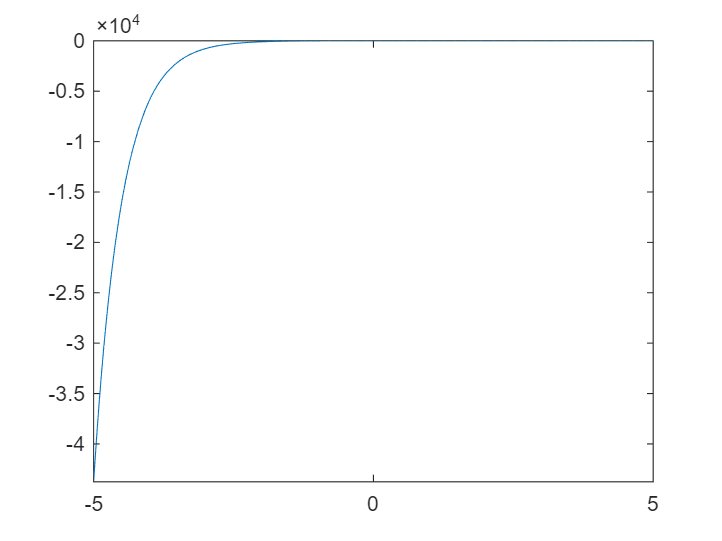

fplot(y2b)

Zastosowanie funkcji *dsolve* domyślnie różniczkuje po zmiennej czasu. Powyższe rozwiązanie korzysta z metody symbolicznej, w związku z czym rozwiązanie przedstawione jest również w formie symbolicznej. 

## Metoda Numeryczna 

Alternatywną metodą rozwiązania równania różniczkowego jest metoda numeryczna. 

Pierwszym krokiem będzie określenie przedziału czasowego na którym wyznaczymy funkcję, oraz określenie warunku początkowego.

% Definiowanie przedziału czasu i warunków początkowych
przedz_cz = [0 5]; % Przedział czasowy od 0 do 5 sekund
y0 = [0; 2]; % Warunki początkowe: x(0) = 0 i Dx(0) = 2

% Definiowanie układu równań różniczkowych pierwszego rzędu 
% y(1) reprezentuje x(t), a y(2) reprezentuje dx/dt.

dydt = @(t, y) [y(2); -3*y(2) - 2*y(1)];

% Rozwiązywanie układu równań za pomocą ode45
[t, y] = ode45(dydt, przedz_cz, y0);

Po wykonaniu powyższego obliczenia, przedstawimy rozwiązanie w formie wykresu, jako że metoda numeryczna nie generuje równania, a jedynie powiązane wartości numeryczne.

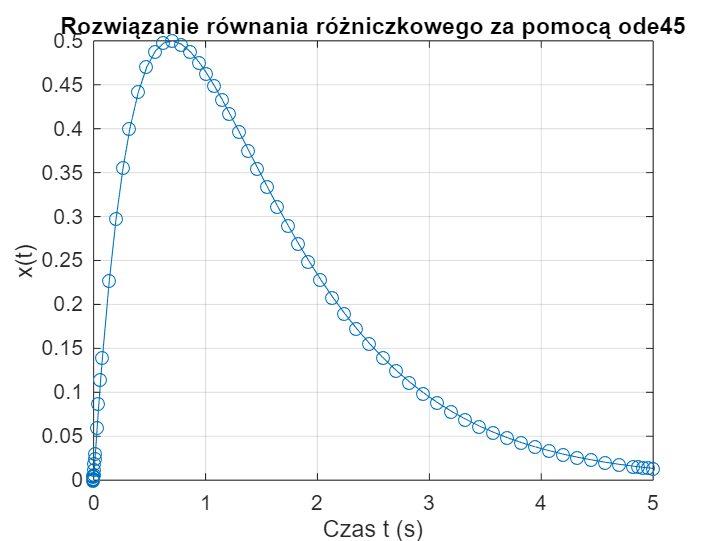

% Rysowanie wykresu dla x(t)
figure;
plot(t, y(:,1), '-o') % Wykres zależności x(t)
xlabel('Czas t (s)')
ylabel('x(t)')
title('Rozwiązanie równania różniczkowego za pomocą ode45')
grid on;

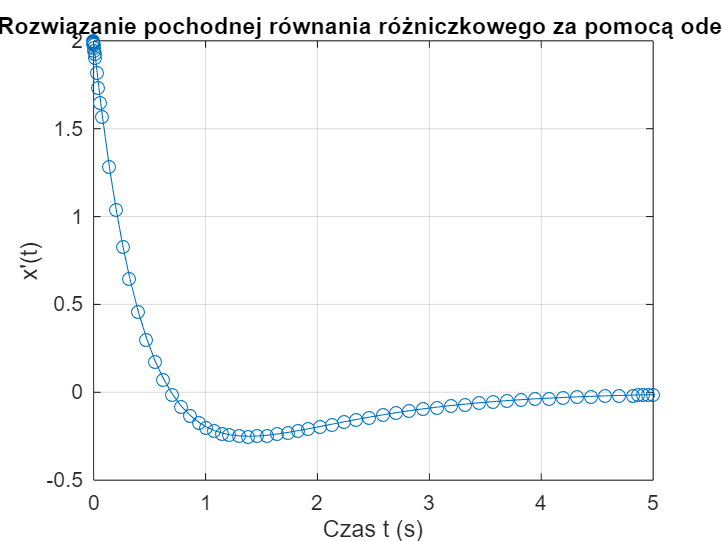

%drawnow;

% Rysowanie wykresu dla pochodnej x'(t)
figure;
%set(gcf, 'Renderer', 'painters');
plot(t, y(:,2), '-o') % Wykres zależności x'(t)
xlabel('Czas t (s)')
ylabel('x''(t)')
title('Rozwiązanie pochodnej równania różniczkowego za pomocą ode45')
grid on;

Metoda rozwiązywania równań różniczkowych ODE45 (metoda Rungego-Kutty 4/5 rzędu) jest najczęściej stosowaną metodą dla ogólnych układów równań różniczkowych o umiarkowanej dokładności i szybkości. Adaptacyjny krok czasu umożliwia uzyskanie wysokiej dokładności.

Szybsza, ale mniej dokładna jest metoda `ode23 (metoda `Rungego-Kutty 2/3 rzędu).

Inne metody to:

- ode15s zalecana dla równań sztywnych, jest bardziej stabilna w takich przypadkach i często szybsza.

- `ode23s` metoda Rosenbrocka 2/3 rzędu, również dla równań sztywnych;

- ode113 przydatna do równań wymagających bardzo dużej dokładności

Podsumowując metody rozwiązwania ODE: 

- `ode45`: uniwersalna, dobra dla większości problemów.

- `ode23`: szybsza, ale mniej dokładna, stosowana do mało sztywnych problemów.

- `ode15s`: zalecane do równań sztywnych.

- `ode113`: najlepsza dla wysokiej dokładności w przypadku mało sztywnych układów.

Każdą z tych metod można wybrać w zależności od dokładności i sztywności układu równań różniczkowych.

Równania różniczkowe są nazywane **sztywnymi**, gdy ich rozwiązanie wymaga bardzo różnych skal czasowych, co oznacza, że potrzebują bardzo małych kroków czasowych, aby zachować stabilność numeryczną, mimo że nie zawsze jest to konieczne dla dokładności.

W kontekście numerycznym, sztywność równań różniczkowych objawia się tym, że standardowe metody rozwiązywania (jak Rungego-Kutty, np. `ode45` w MATLAB-ie) stają się bardzo wolne, ponieważ muszą używać wyjątkowo małych kroków czasowych, aby nie doprowadzić do rozbieżności.

Sztywność występuje często w systemach fizycznych, chemicznych lub biologicznych, w których różne procesy zachodzą z różnymi szybkościami. Na przykład w reakcjach chemicznych jedna reakcja może przebiegać bardzo szybko, podczas gdy inna zachodzi wolniej, co prowadzi do konieczności stosowania bardzo małych kroków w symulacji.

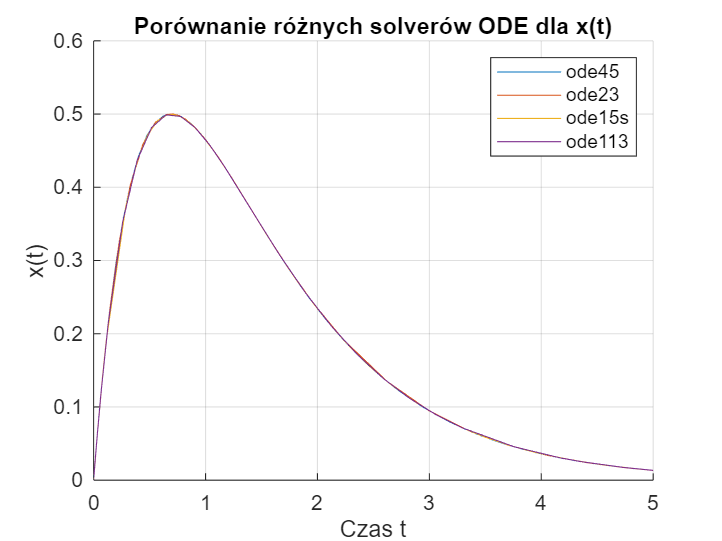

% Definiowanie przedziału czasu i warunków początkowych
przedz_cz = [0 5]; % Przedział czasowy od 0 do 5 sekund
y0 = [0; 2]; % Warunki początkowe: x(0) = 0 i Dx(0) = 2

% Definiowanie układu równań różniczkowych pierwszego rzędu
% y(1) reprezentuje x(t), a y(2) reprezentuje dx/dt.
dydt = @(t, y) [y(2); -3*y(2) - 2*y(1)];

% Lista solverów do porównania
solvers = {@ode45, @ode23, @ode15s, @ode113};
solver_names = ["ode45", "ode23", "ode15s", "ode113"];

% Kolory do wykresów (opcjonalnie, dla czytelności)
colors = lines(length(solvers));

% Tworzenie figury do porównania wyników
figure;
hold on;

% Iteracja po każdym solverze i rozwiązanie układu równań
for i = 1:length(solvers)
    solver = solvers{i};
    [t, y] = solver(dydt, przedz_cz, y0); % Rozwiązanie układu równań
    
    % Rysowanie wyników dla x(t) z każdego solvera
    plot(t, y(:, 1), 'DisplayName', solver_names(i), 'Color', colors(i, :)); % x(t)
end

% Ustawienia wykresu
xlabel('Czas t');
ylabel('x(t)');
title('Porównanie różnych solverów ODE dla x(t)');
legend('show'); % Wyświetlenie legendy z nazwami solverów
grid on;
hold off;